clear
syms alpha1(t) alpha2(t) alpha3(t) alpha4(t) alpha5(t) alpha6(t) alpha7(t) T A
syms w1(t) w2(t) w3(t) w4(t) w5(t) w6(t) w7(t) 
syms theta_c1(t) theta_c2(t) theta_c3(t) theta_c4(t) theta_c5(t) theta_c6(t) theta_c7(t)
assume(T>0)
assume(A>0)
anguloInicialC=-18*pi/180;
anguloFinalC=18*pi/180;
A=10; %rad s^-2
alpha1(t)=9*A/T*t;
alpha2(t)=A;
alpha3(t)=-9*A/T*t;
Ca3=A-alpha3(2*T/9);
alpha3(t)=alpha3(t)+Ca3;
alpha4(t)=0;
alpha5(t)=-9*A/T*t;
Ca5=alpha4(2*T/3)-alpha5(2*T/3);
alpha5(t)=alpha5(t)+Ca5;
alpha6(t)=-A;
alpha7(t)=9*A/T*t;
Ca7=alpha6(8*T/9)-alpha7(8*T/9);
alpha7(t)=alpha7(t)+Ca7;
fprintf('Función de aceleración angular:')

Función de aceleración angular:

alpha(t)=piecewise((0<=t<T/9),alpha1,(T/9<=t<2*T/9),alpha2,(2*T/9<=t<T/3),alpha3,(T/3<=t<2*T/3),alpha4,(2*T/3<=t<7*T/9),alpha5,(7*T/9<=t<8*T/9),alpha6,(8*T/9<=t<T),alpha7)

$$alpha(t) = \left\{ \begin{array}{cl} \frac{90\,t}{T} & \text{ if }9\,t<T\wedge 0\leq t\\ 10 & \text{ if }T\leq 9\,t\wedge 9\,t<2\,T\\ 30-\frac{90\,t}{T} & \text{ if }3\,t<T\wedge 2\,T\leq 9\,t\\ 0 & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ 60-\frac{90\,t}{T} & \text{ if }9\,t<7\,T\wedge 2\,T\leq 3\,t\\ -10 & \text{ if }9\,t<8\,T\wedge 7\,T\leq 9\,t\\ \frac{90\,t}{T}-90 & \text{ if }t<T\wedge 8\,T\leq 9\,t \end{array}\right.$$

w1(t)=int(alpha1);
w2(t)=int(alpha2);
Cw2=w1(T/9)-w2(T/9);
w2(t)=w2(t)+Cw2;
w3(t)=int(alpha3);
Cw3=w2(2*T/9)-w3(2*T/9);
w3(t)=w3(t)+Cw3;
w4(t)=w3(T/3);
w5(t)=int(alpha5);
Cw5=w4(2*T/3)-w5(2*T/3);
w5(t)=w5(t)+Cw5;
w6(t)=int(alpha6);
Cw6=w5(7*T/9)-w6(7*T/9);
w6(t)=w6(t)+Cw6;
w7(t)=int(alpha7);
CW7=w6(8*T/9)-w7(8*T/9);
w7(t)=w7(t)+CW7;
fprintf('Función de velocidad angular:')

Función de velocidad angular:

w(t)=piecewise((0<=t<T/9),w1,(T/9<=t<2*T/9),w2,(2*T/9<=t<T/3),w3,(T/3<=t<2*T/3),w4,(2*T/3<=t<7*T/9),w5,(7*T/9<=t<8*T/9),w6,(8*T/9<=t<T),w7)

$$w(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }9\,t<T\wedge 0\leq t\\ 10\,t-\frac{5\,T}{9} & \text{ if }T\leq 9\,t\wedge 9\,t<2\,T\\ 30\,t-\frac{25\,T}{9}-\sigma_{1} & \text{ if }3\,t<T\wedge 2\,T\leq 9\,t\\ \frac{20\,T}{9} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ 60\,t-\frac{160\,T}{9}-\sigma_{1} & \text{ if }9\,t<7\,T\wedge 2\,T\leq 3\,t\\ \frac{85\,T}{9}-10\,t & \text{ if }9\,t<8\,T\wedge 7\,T\leq 9\,t\\ 45\,T-90\,t+\sigma_{1} & \text{ if }t<T\wedge 8\,T\leq 9\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{45\,t^{2}}{T} \end{array}$$

theta_c1(t)=int(w1)+anguloInicialC;
theta_c2(t)=int(w2);
Ctheta_c2=theta_c1(T/9)-theta_c2(T/9);
theta_c2(t)=theta_c2(t)+Ctheta_c2;
theta_c3(t)=int(w3);
Ctheta_c3=theta_c2(2*T/9)-theta_c3(2*T/9);
theta_c3(t)=theta_c3(t)+Ctheta_c3

$$theta\_c3(t) = \frac{5\,T^{2}}{27}-\frac{25\,T\,t}{9}-\frac{\pi }{10}+15\,t^{2}-\frac{15\,t^{3}}{T}$$

theta_c4(t)=int(w4);
Ctheta_c4=theta_c3(T/3)-theta_c4(T/3);
theta_c4(t)=theta_c4(t)+Ctheta_c4;
theta_c5(t)=int(w5);
Ctheta_c5=theta_c4(2*T/3)-theta_c5(2*T/3);
theta_c5(t)=theta_c5(t)+Ctheta_c5;
theta_c6(t)=int(w6);
Ctheta_c6=theta_c5(7*T/9)-theta_c6(7*T/9);
theta_c6(t)=theta_c6(t)+Ctheta_c6;
theta_c7(t)=int(w7);
Ctheta_c7=theta_c6(8*T/9)-theta_c7(8*T/9);
theta_c7(t)=theta_c7(t)+Ctheta_c7;
fprintf('Función de desplazamiento angular:')

Función de desplazamiento angular:

Ftheta_c(t)=piecewise((0<=t<T/9),theta_c1,(T/9<=t<2*T/9),theta_c2,(2*T/9<=t<T/3),theta_c3,(T/3<=t<2*T/3),theta_c4,(2*T/3<=t<7*T/9),theta_c5,(7*T/9<=t<8*T/9),theta_c6,(8*T/9<=t<=T),theta_c7)

$$Ftheta\_c(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1}-\frac{\pi }{10} & \text{ if }9\,t<T\wedge 0\leq t\\ \frac{5\,T^{2}}{243}-\frac{5\,t\,\left(T-9\,t\right)}{9}-\frac{\pi }{10} & \text{ if }T\leq 9\,t\wedge 9\,t<2\,T\\ \frac{5\,T^{2}}{27}-\frac{25\,T\,t}{9}-\frac{\pi }{10}+15\,t^{2}-\sigma_{1} & \text{ if }3\,t<T\wedge 2\,T\leq 9\,t\\ -\frac{10\,T^{2}}{27}+\frac{20\,t\,T}{9}-\frac{\pi }{10} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ \frac{110\,T^{2}}{27}-\frac{160\,T\,t}{9}-\frac{\pi }{10}+30\,t^{2}-\sigma_{1} & \text{ if }9\,t<7\,T\wedge 2\,T\leq 3\,t\\ \frac{5\,t\,\left(17\,T-9\,t\right)}{9}-\frac{725\,T^{2}}{243}-\frac{\pi }{10} & \text{ if }9\,t<8\,T\wedge 7\,T\leq 9\,t\\ 45\,T\,t-\frac{\pi }{10}-\frac{365\,T^{2}}{27}-45\,t^{2}+\sigma_{1} & \text{ if }t\leq T\wedge 8\,T\leq 9\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{15\,t^{3}}{T} \end{array}$$

f=0==Ftheta_c(T/2);
tMax_c=solve(f,T)

$$tMax\_c = \frac{3\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{20}$$

alpha=subs(alpha,T,tMax_c);
w=subs(w,T,tMax_c);
Ftheta_c=subs(Ftheta_c,T,tMax_c);

## Gráficas

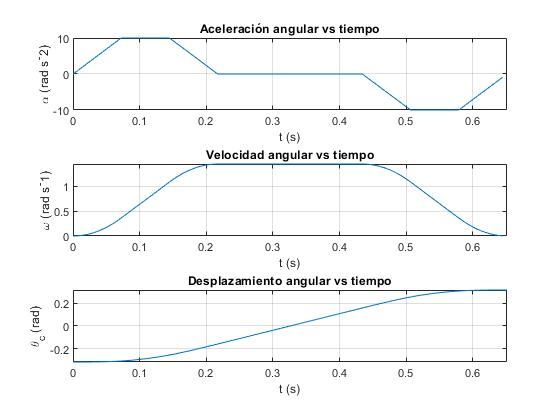

ts=linspace(0,tMax_c,100);
figure()
subplot(3,1,1)
plot(ts,alpha(ts))
title('Aceleración angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\alpha (rad s^-2)')
xlim([0 double(tMax_c)])
subplot(3,1,2)
plot(ts,w(ts))
title('Velocidad angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\omega (rad s^-1)')
xlim([0 double(tMax_c)])
subplot(3,1,3)
plot(ts,Ftheta_c(ts))
title('Desplazamiento angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\theta_c (rad)')
xlim([0 double(tMax_c)])


clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada
